## Le cose da sapere di MatLab

Cose da mettere all'inizio di ogni script

clc;
clear;
close all;

Se non si mette il **;** alla fine di una riga la stampa

**Variabili:**

x = 1;
a = "string";

**Operatori**

+ somma

- sottrazione

* prodotto matriciale

.* prodotto elemento per elemento

^ potenza

.^ potenza elemento per elemento

**Loop**

for index = initVal:endVal
    % corpo for
end

*index = initVal* sarebbe l'equivalente di *int index = 0*

*initVal:endVal *serve per capire che il for va da *initVal *a *endVal ***compresi**

while condition
    % corpo while
end

**Condizioni**

if condition
    % corpo if
elseif
    % corpo elseif
else
    % corpo else
end

**Operatori di confronto**

==            uguale

~=            diverso

<              minore

>              maggiore

>= e <=   maggiore uguale e mimore uguale

**Operatore di assegnamento **=

**NON FARE if(det(A) == 0)...**

**Fai invece:**

if(abs(det(A)) < 1e-10)
    error("la matrice non è invertibile");
end

**Switch**

switch switch_expression
    case case_expression
        % corpo caso 1
    otherwise
        % corpo caso default
end

**Print output**

Le semplici variabili in questo modo

x = 1

come le operazioni

x + y

Oppure in questa maniera:

disp("testo stampato")

**Input**

inputValue = input("prompt a schermo", "s");

Dove il *segnaposto ****s*** può essere sostituito da:

- s => per le stringhe

- *niente* (default) => per numeri imteri o decimali, array

**Costanti**

pi      % Sarebbe il π pi Greco
exp(1)  % Sarebbe il numero di Nepero e
i       % È il numero immaginario e può essere i oppure j
inf     % Sarebbe infinito (1/0)
nan     % Sta per Not A Number come (0/0)

**Formato delle variabili**

Questo non cambia il loro valore reale ma solo la rappresentazione su schermo

Si usa la keyword `format`

- `format short ``=> di default fa visualizzare 4 numeri dopo la virgola`

format short
% Variable, e.g. pi
pi     % ans = 3.1416

- `format short e ``=> permette di mostrare il numero in notazione scientifica`

format short e

iMin = -1

pi      % ans = 3.1416e+00

iMax = 10

- Poi esistono `format long` ecc

**Arrotondamento o troncamento**

- **TRONCAMENTO:** `fix`

fix(pi)     % restituisce 3

n = 5

- **ARR. DIFETTO: **`floor`

floor(1.9)  % restituisce 1

A =     3.1642    3.1133    8.4035    2.9256    4.7173
    8.3112    1.7411    9.9658    9.5228    0.8209
    1.5637    2.9414   -0.5619    3.8180    0.9438
    3.9014    9.3202   -0.6934    5.8888    5.5208
    6.0087    3.7753    0.5031    5.5030    7.9898


- **ARR. ECCESSO:** `ceil`

ceil(1.1)   % restituisce 2

- **BUON ARROTONDAMENTO:** `round`

round(1.1)  % restituisce 1
round(1.9)  % restituisce 2
round(1.5)  % restituisce 2

`round` può avere anche altri parametri

%round(pi, n) % dove n è il numero di cifre alla quale arrotondare

Si usa la keyword `"significant"` per poter prendere solo le cifre più significanti

Ipotizzando di avere: 

`x = 0.000023542` 

e 

`y = 12.352`

round(x, 2, "significant") % restituisce 0.0024
round(y, 2, "significant") % restituisce 12

Senza `"significant"`

round(x, 2)                % restituisce 0

A =     0.2638    0.8693    0.1450
    0.1455    0.5797    0.8530
    0.1361    0.5499    0.6221


round(y, 2)                % restituisce 12.35

V =    -0.5496   -0.9814    0.9319
   -0.6406    0.1811   -0.3493
   -0.5362    0.0643    0.0976


D =     1.4185         0         0
         0    0.0939         0
         0         0   -0.0469


**ERRORE ASSOLUTO E RELATIVO**

- ASSOLUTO: è la differenza tra il numero originale e lo stesso numero arrotondato

errAbs = abs(x - xArr)

D =     1.4185
    0.0939
   -0.0469


- RELATIVO: sarebbe la relazione tra l'errore assoluto e il valore assoluto del numero non arrotondato

errRel = errAbs / abs(x)

rho = 1.4185

- ASSOLUTO SU VETTORI

errAbsVett = norm(x - x1)

d_sort =     1.4185
    0.0939
    0.0469


- RELATIVO SU VETTORI

errRel = errAbsVett / norm(x)    % o semplicemente: errRel = norm(x - x1) / norm(x);

rho = 1.4185

**EPSILON MACHINA = 2.220446049250313e-16**

È il numero più piccolo che sommato ad 1 ci da un numero diverso da 1

Di seguito il codice per trovarlo

ep = 1;
flagRipeti = true;
k = 0;
while (flagRipeti)

rho = 1.4185

    ep = ep/2;
    x = 1+ep;
    flagRipeti = (x > 1);
    k = k+1;
end

ep = ep * 2;

**VETTORI**

- vettore riga

xr = [1,2,3,4,5]

- vettore colonna

xc = [1;2;3;4;5]

- vettore dichiarato con gli spazi

yr = [1 2 3 4 5]

f = function_handle with value:
    @(x)cos(x)


- per farlo diventare vettore colonna basta mettere l'apice a fine dichiarazione per fare la matrice trasposta

yc = [1 2 3 4 5]'

x =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


- Puoi generare un vettore impostando un *intervallo tra *`x`* e *`y` (compresi) e un *passo(incremento) *`p`

v = x : p : y
% e.g. =>   v = 0 : 1 : 10   => [0 1 .. 9 10]

**Generazione automatica di un vettore**

Si usa il comando `linspace(..)` che come parametri ha: `iMin`, `iMax` e `n` e genera un vettore riga di n elementi da iMin a iMax

x = linspace(iMin, iMax, n)

**Operazioni tra vettori**

- **Somma +, Sottrazione -, Moltiplicazione ***

- **Moltiplicazione elemento per elemento: .***

e.g. per la moltiplicaziotore elemento per elemento di due vettori simili (inteso come entrambi riga o entrambi colonna) si ottiene un altro vettore con il primo elemento di v1 moltiplicato per il primo di v2 e così via.

**MATRICI**

MatLab *memeorizza tutto in matrici*, anche gli scalari sono matrici 1x1

Per dichiarare una matrice (*per convenzione indicato con lettere iniziali MAIUSCOLE*) ci sono diversi modi:

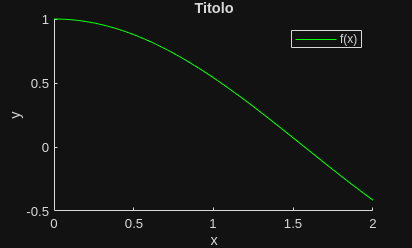

A1 = [1 2 3;
     4 5 6;
     7 8 9]

% oppure

v1 = [1 2 3]
v2 = [4 5 6]

v3 = [7 8 9]

A2 = [v1;v2;v3]    % Si poteva dichiarare anche A2 = [v1 v2 v3]
% La matrice sarebbe UGUALE a A1

%{
    La matrice trasposta (con ' alla fine della dichiarazione) sarebbe
    {[1 4 7]
     [2 5 8]
     [3 6 9]}
    con le righe al posto delle colonne
%}

% Un altro modo per dichiarare una matrice è:
A1 = [1 2;
      3 4]
A2 = [5 6;
      7 8]
A3 = [9 10;
      11 12]

A = [A1 A2;
     A3 A1]

**Modo casuale di generazione di matrici e vettori**

Fino ad ora abbiamo fatto in maniera esplicita, ora vediamo maniera implicita

rand    % crea un numero casuale compreso tra 0 e 1

per creare una matrice quadrata 3x3 casuale si fa

rand(3)

per fare una matrice rettangolare e.g. 3x4 si fa

A = rand(3,4)

creo un vettore size e posso passarlo all'interno dell'input di rand per creare una matrice casuale

sz = [3 4]
A1 = rand(sz)
% oppure tramite variabili
lines = 3
rows = 4
A2 = rand(lines, rows)

randn crea una matrice nxm ma i valori seguono una distribuzione normale

B = randn(lines, rows)

randi genera una matrice nxm con numeri interi, la sua sintassi è:

`randi(imax,par2, par3..)`

in cui:

` - imax` nel caso sia uno scalare è il valore massimo che può assumere un elemento nella matrice (tra 0 e imax)

         └>  nel caso sia un vettore indica l'intervallo nel quale generare i valori, e.g. `imax = [10 20];` genera valori tra 10 e 20 compresi

 -   `par2 `indica le **righe della matrice **oppure anche le colonne nel caso sia questo l'ultimo parametro

` - par3 `indica le colonne della matrice

randi(imax, rows, cols)

Di conseguenza è possibile anche creare vettori riga randomici imponendo le righe a 1, oppure vettori colonne imponendo le colonne a 1

Ipotizziamo di creare una matrice `nxn` di valori decimali compresi in un intervallo `[iMin, iMax]`

A = (iMax-iMin) * rand(n) + iMin

**Spiegazione**:

rand(n) genera una matrice `nxn` di numeri compresi tra 0 e 1, moltiplicato per `iMax` otteniamo numeri tra 0 e `iMax`, ora sottraendo `iMin` otteniamo l'intervallo desiderato

iMin = -1
iMax = 10
n = 5
A = (iMax-iMin) * rand(n) + iMin

**Inizializzare una matrice**

Per inizializzare (tutta a 0) una matrice si usa `zeros` 

zeros(rows, cols)

% oppure una matrice quadrata
zeros(rowsCols)

Per inizializzarla tutti 1 si usa `ones` 

ones(rows, cols)

Per creare una matrice identità si usa `eye` 

eye(n)
%{ 
    n = 3
    ans =
        {[1 0 0]
         [0 1 0]
         [0 0 1]}
%}

**Accedere agli elementi di una matrice**

In MatLab la prima posizione dell'array è 1 e NON 0

In una classica matrice si usa:

A(elementInRow, elementInCol)

È possibile prendere anche parte della matrice, ad esempio prendere dalla riga `w` alla riga `x` e dalla colonna `y` alla colonna `z`:            (**SEMPRE VALORI COMPRESI**)

A(w:x, y:z)

Al posto dell'intervallo si può usare `:` per indicare di prendere tutti gli elementi di riga o colonna, e.g. `A(w:x, :)` ovvero prendere tutti gli elementi delle righe dalla `w` alla `x` comprese.

Al posto di indicare l'ultima riga/colonna si può usare la keyword `end`

A(w:end, y:end)

**Modificare gli elementi di una matrice**

A(r, c) = n    % Imposta l'elemento in posizione (r, c) a n
A(r, :) = n    % Imposta tutti gli elementi della riga r a n
A(:, c) = n    % Imposta tutti gli elementi della colonna c a n

**Dimensione della matrice**

Per ottenere la dimensione di una matrice si usa il comando `size` che restituisce un vettore che indica `[rows, cols]`

Per ottenere solo le righe o solo le colonne si usa come secondo parametro di `size`:

` - 1` per le righe

` - 2` per le colonne

**Determinante della matrice**

Per calcolare il determinante di una matrice si usa il comando `det`:

det(A)

**Matrice inversa**

Per calcolare la matrice inversa basta elevarla a `-1` 

Ainv = A^-1

**Rango della matrice**

Per ottenere il rango della matrice si usa il comando `rank`:

rank(A)

**Norme**

Le norme sono ottenibili dal comando `norm`:

norm(A, 2)    % È la norma 2, è l'equivalente di scrivere norm(A)
norm(A, 1)    % È la norma 1
norm(A, inf)  % È la norma infinito

**Matrici di differenti tipi**

- Matrici trinagolari:

U = triu(A)     % estrae la matrice triangolare superiore di A
L = tril(A)     % estrae la matrice triangolare inferiore di A

D = diag(diag(A))     % diag = diagonale di A (in vettore colonna)
                      % diag(diag) = matrice della diagonale di A

B = L - D        % matrice triang. inf. senza la diagonale
% Oppure:
L2 = tril(A, -1)


isequal(A, (L2 + D + U))

Ricorda che la matrice diagonale è sia triangolare superiore che inferiore

istriu(U)       %comando per vedere se è una matrice triangolare superiore (upper)
istril(L)       %comando per vedere se è una matrice triangolare inferiore (lower)

istriu(D)
istril(D)

isdiag(D)       %determina se la matrice è diagonale

Per verificare se una matrice è hermittiana (quando è uguale alla sua trasposta coniugata) si usa:

ishermitian(A)  % Sarebbe: isequal(A, A')

Per vedere se la mia matrice è **ortogonale**:

**CREIAMO UNA FUNZIONE CHE FACCIA **`isorth(..)`

importiamo il file isorth.m

**A * x = b**

Come trovare la soluzione di A * x = b?

A = rand(3)
b = ones(3, 1)      %vettore colonna soluzione

%come trovare il vettore soluzione x?
%x = inv(A)*b 
% oppure:
x = A\b     % NB \ è diverso da /

`x = A\b` sarebbe come $x=\frac{b}{A}$ ed è più veloce ed efficente in termini di computazione rispetto che `inv(A)*b`.

**Autovettori e autovalori**

Calcolo autovettori e autovalori:

A = rand(3)
[V, D] = eig(A)          %autovalori della matrice
%V = Autovettori
%D = Autovalori
D = diag(D)             %spettro della matrice

Cercare il raggio spettrale

rho = max(abs(D))

%oppure
d_sort = sort(abs(D), 'descend')    %descend ovvero dal più grande al più piccolo, di default è 'ascend'
rho = d_sort(1)

%oppure
%eigs: da un subset degli autovalori e autovettori, ovvero gli diciamo noi quanti ne vogliamo avere
rho = eigs(A, 1, 'largestabs');
%restituisce l'autovalore in abs più grande ma con il suo segno
% quindi tra 1 -7 6 restituisce -7
rho = abs(eigs(A, 1, 'largestabs'))    %in questo caso restituisce il valore in abs

**GRAFICI**

**NB** Fai i grafici su file `.m` non `.mlx`

immaginiamo di avere come x un vettore di numeri, in y il seno di ogni elemento di x (`y = sin(x)`) e in x il coseno di ogni elemento di x (`y = sin(x)`):

figure;             % Apre una finestra dedicata al grafico
p = plot(x, y, 'LineWidth', value, 'Color',"colorValue", 'LineStyle','style');
    %{
        - x e y sono i valori di ascisse e ordinate
        - LineWidth indica lo spessore e value è il valore che assume (intero)
        - Color indica il colore della curva e colorValue è il colore che assume (e.g. r = red, b = blue, k = black, g = green)
            è possibile scrivere anche lo stile della curva in questa posizione (e.g. r--)
            prima del colore è possibile inserire le intersezioni con l'asse delle x (e.g. o, +, *, ., x  =>  che verranno usati per le intersezioni)
        - LineStyle indica lo stile indicato da style (e.g. - = continua, -- = tratteggiata, : = puntinata, -. = tratto-punto)
    %}
title("Titolo del grafico")
xlabel("x")
ylabel("y & z")
grid on             % Attiva la griglia nel grafico
hold on             % Serve per non cancellare il primo grafico quando disegno il secondo

% plot simile a quello di prima ma per x ascissa e z ordinate

legend('nome primo plot (e.g. sin(x)', 'nome secondo plot', ..)

A `plot` esiste un'aggiunta chiamata `"DisplayName"` che permette di inserire a seguire un nome per fare la legenda in automatico

e.g.

plot(x, y, "ob", "DisplayName", "Seno", ..);

legend

Qualsiasi dubbio nel terminale di MatLab scrivi `help plot`

**FUNZIONI A VARIABILI**

È possibile assegnare a una variabile (e.g. f) una funzione (e.g. cos) in questa maniera:

f = @(x) cos(x)
% E poi creare i valori che devono essere restituiti dalla funzione (e.g. 100 elementi dell'intervallo da 0 a 2)
x = linspace(0, 2, 100)

Per poi conseguentemente riportarlo nel plot

figure;
hold on;

title("Titolo");
xlabel("x");
ylabel("y");

plot(x, f(x), "-g", "DisplayName", "f(x)");

legend();

hold off;

**TABELLE**

Per creare una tabella si usa la keyword `table` e funziona così:

t = table(el1, eln, 'VariableNames', {'Name1', 'NameN'});
% e per mostrarla
disp(t);

Immaginiamo di avere come `el1` i numeri da 1 a 10 e come `eln` il suo doppio (entrambi come **vettori colonna**), avremo come output una cosa del genere:

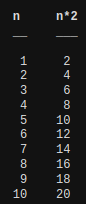

**RENDERE UNA MATRICE *****DIAGONALMENTE DOMINANTE***

Per rendere una matrice **diagonalmente dominante**, devi assicurarti che in ogni riga il valore assoluto dell'elemento sulla diagonale principale sia maggiore (o uguale) alla somma dei valori assoluti di tutti gli altri elementi della stessa riga

A = A - diag(diag(A));
s = sum(abs(A));           %Il vettore contiene la somma di tutti i valori assoluti della colonna
s = s + 0.1;
A = A + diag(s);